# Half-Car Simulink Model Test

car.sprungMass = 300; % kg
car.pitchInertia = 80; % whatever tf the SI unit is for this
car.unsprungMass = 12; % kg
car.wheelbase = 1.53; % m
car.CGx = 0.45; % ratio fwd
car.CGh = 0.3; % m

car.frontInertance = 0; % kg
car.rearInertance = 0; % kg
car.frontTireStiffness = 114000; % N/m
car.frontTireDamping = 400; % Ns/m
car.rearTireStiffness = 114000;
car.rearTireDamping = 400;

%% Read Damper/Spring Plots
frontMR = 1.0; % Motion Ratio
rearMR = 1.2;

frontSpringCurve = SetSpringCurve(readtable("SpringTable.xlsx", "Sheet", "linear_350"), frontMR);
rearSpringCurve = SetSpringCurve(readtable("SpringTable.xlsx", "Sheet", "linear_300"), rearMR);

damperTable = readtable("DamperTable.xlsx","Sheet","Multimatic_DSSV_VC01"); % Change damper plots here

frontDamperCurve = SetDamperClick(damperTable, frontMR, 6, 6); % (table, compression, rebound)
rearDamperCurve = SetDamperClick(damperTable, rearMR, 6, 6);

%% Single Run
run = SingleRun(car, frontDamperCurve, rearDamperCurve, frontSpringCurve, rearSpringCurve);    



## Debug Plots

t = run.logsout.get("Front CPL").Values.Time;

frontCPL = run.logsout.get("Front CPL").Values.Data;
rearCPL = run.logsout.get("Rear CPL").Values.Data;

frontBodyDisplacement = run.logsout.get("Front Body Displacement").Values.Data;
rearBodyDisplacement = run.logsout.get("Rear Body Displacement").Values.Data;

frontHubDisplacement = run.logsout.get("Front Hub Displacement").Values.Data;
rearHubDisplacement = run.logsout.get("Rear Hub Displacement").Values.Data;

Fs = 1/(t(2)-t(1)) % change based on t of simulation

Fs = 1000

f = Fs/length(frontCPL)*(0:length(frontCPL)-1);

frontCPLfft = fft(frontCPL)

frontCPLfft = 1.0e+07 *

   3.1196 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0001i
  -0.0000 - 0.0001i
  -0.0000 - 0.0001i
  -0.0000 - 0.0001i
  -0.0000 - 0.0001i
  -0.0000 - 0.0002i
  -0.0000 - 0.0002i
  -0.0000 - 0.0002i
  -0.0000 - 0.0002i
  -0.0000 - 0.0002i
  -0.0000 - 0.0003i
  -0.0000 - 0.0003i


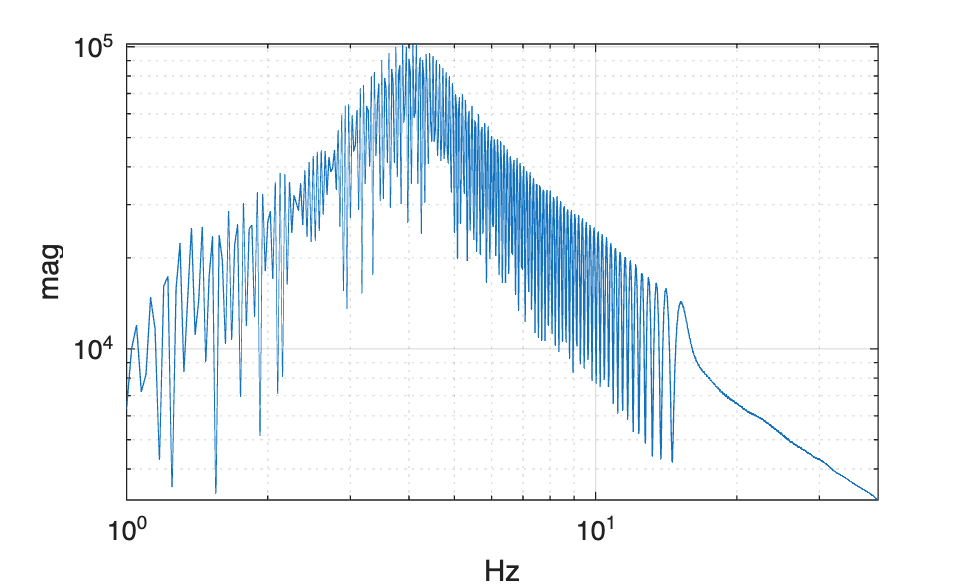


figure
loglog(f, abs(frontCPLfft));
xlim([1,40]);
grid on
xlabel("Hz");
ylabel("mag");

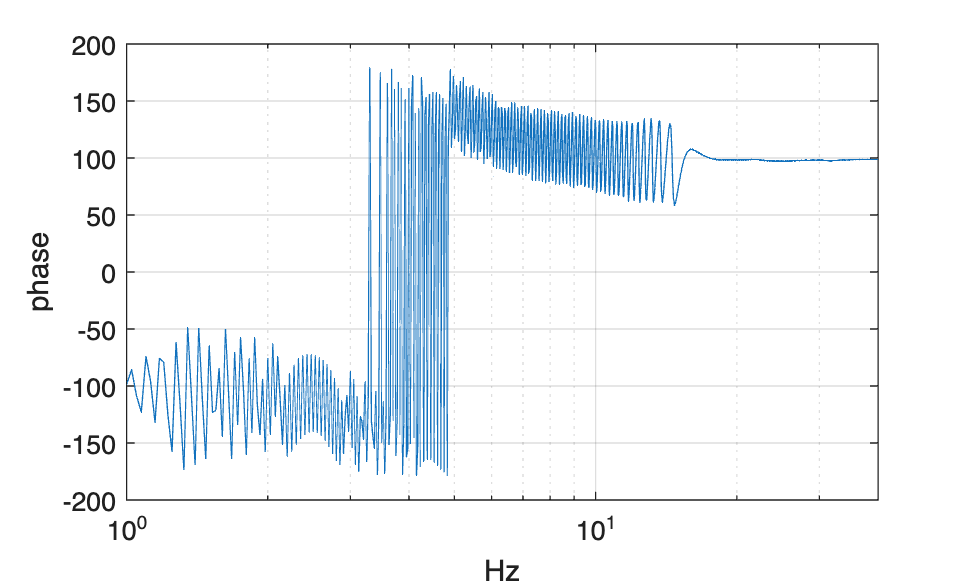


figure
semilogx(f, rad2deg(angle(frontCPLfft)));
xlim([1,40]);
grid on
xlabel("Hz");
ylabel("phase");